# Exploring Gaussian Elimination

## Introduction

One of the main applications of matrices is solving simultaneous equations of the form:


$$\begin{array}{l}
a_{11} x_1 +a_{12} x_2 +\cdots +a_{1n} x_n =b_1 \\
a_{21} x_1 +a_{22} x_2 +\cdots +a_{2n} x_n =b_2 \\
\vdots \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\vdots \\
a_{\textrm{n1}} x_1 +a_{\textrm{n2}} x_2 +\cdots +a_{\textrm{nn}} x_n =b_n 
\end{array}$$


Here $x_1 ,x_2 ,\cdots ,x_n$ are the variables (unknowns) and the coefficients $a_{ij}$ and $b_i$ are given real numbers. This set of equations can be written using matrix multiplication as:


$$A\underline{\mathbf{\mathit{x}}}=\underline{\mathbf{\mathit{b}}}$$


where $\underline{\mathbf{\mathit{x}}}$ is a column vector of unknowns, $\underline{\mathbf{\mathit{b}}}$ is a given $m\times 1$ matrix (column vector) and $A=\left(a_{ij}\right)$ is the $m\times n$ matrix of coefficients. An efficient way of solving a system is by *Gaussian Elimination *which involves the use of the *augmented matrix *$\left(A\left|\underline{b} \right.\right)$.

In this activity we will explore the basic commands used to reduce an augmented matrix to row echelon form and solve a system equations.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read carefuly each section. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

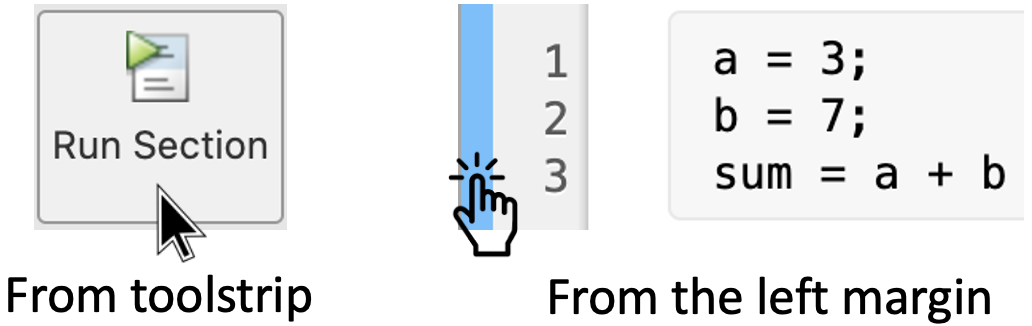

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. How to solve a system of equations

Matrices are entered in MATLAB by typing the elements within square brackets `[]`, much like we did with vectors. These can be written using commas or spaces to separate the elements in a row and using a semicolon to separate rows. For example, the system

 $\begin{array}{rc}
x_1+2x_2-3x_3 &=&-1\\
-3x_1-4x_2+8x_3&=&3 \\
2x_1+5x_2-8x_3 &=&-5
\end{array}$              (1)

can be described using the matrices:


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & -3\\
-3 & -4 & 8\\
2 & 5 & -8
\end{array}\right\rbrack ,\;\underline{x} =\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack ,\;\underline{b} =\left\lbrack \begin{array}{c}
-1\\
3\\
-5
\end{array}\right\rbrack \ldotp$$


So, for instance, in order to define $A$, we need to use the following code:

A = [1,2,-3;-3,-4,8;2,5,-8]

### 1.1 Example 1 - Finding the row reduced matrix with `rref()`

The row reduced form of a matrix can tell us a lot about the system, particularly how many solutions the system has. We can use the command [`rref`](https://au.mathworks.com/help/matlab/ref/rref.html) to find this reduced form very quickly - without all the hassle of many lines of algebra using elementary row operations! 


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & -3\\
-3 & -4 & 8\\
2 & 5 & -8
\end{array}\right\rbrack ,\;\underline{x} =\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack ,\;\underline{b} =\left\lbrack \begin{array}{c}
-1\\
3\\
-5
\end{array}\right\rbrack \ldotp$$


Using the system defined in (1), we can use the [`rref`](https://au.mathworks.com/help/matlab/ref/rref.html) command with matrix $A$ as below:

rref(A)

This function gives the Gauss-Jordan reduction for this matrix. What does the reduced row echelon form above tell us about the system? How many solutions does this system have?

Using the **augmented matrix** instead, we can see solutions for $x_1$, $x_2$ and $x_3$ right away:

b = [-1;3;-5]; % the right hand side of the system above
Ag = [A,b];    % the augmented matrix for the system
rref(Ag)

What are solutions for $x_1$, $x_2$ and $x_3$?

Try to find the reduced row echelon form by hand yourself and compare your results to those above. You can also compare your findings to the example on page 130 of the workbook.

## 2. Creating and solving a system of equations

To create and use a system of equations, we can use the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`equationsToMatrix`](https://au.mathworks.com/help/symbolic/sym.equationstomatrix.html). These commands allow us to enter the equations exactly as they might appear in a problem, for example:


$$\begin{array}{rc}
x_1+2x_2-3x_3 &=&-1\\
-3x_1-4x_2+8x_3&=&3 \\
2x_1+5x_2-8x_3 &=&-5
\end{array}$$


The following examples demonstrate how to turn this system into a matrix of coefficients and vector that represents the right-hand side.

### 2.1 Example 2 - Defining equations

Let us use the system of equations above:

syms x1 x2 x3
eqn1 = x1 + 2*x2 - 3*x3 == -1
eqn2 = -3*x1 - 4*x2 + 8*x3 == 3
eqn3 = 2*x1 + 5*x2 - 8*x3 == -5

**Note 1:** The use of symbolic variables allows us to setup equations with a left- and right-hand side. We need the "`==`" symbol to assign the right-hand side of an equation, while we use the single "`=`" to assign the entire equation to a variable in MATLAB (`eqn1`, `eqn2` or `eqn3 `in this case).

### 2.2 Example 3 - Building matrices

We can [`equationsToMatrix`](https://au.mathworks.com/help/symbolic/sym.equationstomatrix.html;jsessionid=85d91f9133a1398469625150cdf8) to convert the equations into the form $A\underline{\mathbf{\mathit{x}}}=\underline{\mathbf{\mathit{b}}}$. The first input defines the equations (as above) and the second defines the variables we are using in this problem.

[A,b] = equationsToMatrix([eqn1, eqn2, eqn3], [x1, x2, x3])

### 2.3 Example 4 - Solving the system using `linsolve()`

Now that we have $A$ and $\underline{\mathbf{\mathit{b}}}$ we can solve the system using the command [`linsolve`](https://au.mathworks.com/help/matlab/ref/linsolve.html).

In the following example we will use this command to get a particular solution to our system:

x = linsolve(A,b)

See how your results from example 1 compare here!

### 2.4 Example 5 - Checking for more solutions using `null()`

The nullspace (denoted $\textrm{NS}\left(A\right)$) of a matrix can give us lots of useful information about a system and it is found by solving: $A\underline{\mathbf{\mathit{x}}}=\underline{\mathbf{\mathit{0}}}$. The nullspace is related to the solutions of the system $A\underline{\mathbf{\mathit{x}}}=\underline{\mathbf{\mathit{b}}}$ through$\left\lbrace \underline{\mathit{\mathbf{x}}} =\underline{\mathit{\mathbf{p}}} +\underline{\mathit{\mathbf{y}}} \left|\underline{\mathit{\mathbf{y}}} \in \textrm{NS}\left(A\right)\right.\right\rbrace$, where $\underline{\mathit{\mathbf{p}}}$ is a *particular* solution.

The solution to the system above is, in fact, the only solution. We can check this using the command [`null`](https://au.mathworks.com/help/matlab/ref/null.html), which gives us elements in the nullspace of the matrix $A$.

For example, run the following code:

NSA = null(A)

Here we have no elements in our nullspace. This tells us that we have **only one** solution to the system above - the particular solution.

**Note 2: **Observe that the command `null` produces a result that is *empty *in MATLAB for this example. However, the nullspace is **never** empty - since it always contains *at least* the 0 vector.

Run the following code instead and check the nullspace of this new matrix:

C = [1,-2,4;2,-3,9;5,-9,21]; 
NSC = null(C)

What do you notice about the elements in the nullspace? Are they "nice looking" numbers?

NSCr = null(C,'r') % the optional input r gives us rational answers

The optional input parameter `'r'` gives us nicer answers. Remember that** any scalar multiple** of a nullspace element can be used in the solution to a system of equations.

## 3. Hands on Practice

Let's practice what we just learned. 

### 3.1 Solving systems of equations

### Activity 1:

At the start of the workshop, you solved the following system of linear equations by hand:


$$\begin{array}{l}
\;\;\;\;\;\;w+\;\;\;2x-\;\;\;y+2z=4\\
-2w-\;\;\;3x+4y-2z=0\\
\;\;\;\;4w+\;\;\;5x-9y+5z=-1\\
\;\;\;\;5w+13x-5y-\;\;\;z=4
\end{array}$$


Use MATLAB and [`rref`](https://au.mathworks.com/help/matlab/ref/rref.html) to solve this system of equations and use [`null`](https://au.mathworks.com/help/matlab/ref/null.html) to verify the number of solutions. 

Write you code here:

### Activity 2:

There has been a natural disaster on an island off the coast of Australia and you have been hired by the United Nations to help with the distribution of canned food. The only available rations are the canned goods A, B and C. 

To avoid permanent health issues, the survivors must receive 12 mg of nutrient P, 14 mg of nutrient Q and 6 mg of nutrient R. Each can provides nutrients as below:

- One can of **A** provides 2 mg of nutrient P and 14 mg of nutrient R. 

- The only source of nutrient Q is can **B** which provides 4 mg per can. However, one can of B also consumes 1 mg of nutrient P and 10 mg of nutrient R. 

- Finally, one can of **C** provides 3 mg of nutrient P but consumes 2 mg of nutrient Q.

Resources are in short supply, so you must ensure that you distribute the food as efficiently as possible. Use MATLAB and [`rref`](https://au.mathworks.com/help/matlab/ref/rref.html) to determine the quantity of cans that every person should be given to avoid permanent health issues.

Write you code here:

### 3.2 Solutions and the nullspace

Consider the system:

$A=\left\lbrack \begin{array}{ccc}
1 & 3 & -2\\
-1 & 1 & -2\\
2 & 4 & -2
\end{array}\right\rbrack$ with $\underline{\mathit{\mathbf{b}}} =\left\lbrack \begin{array}{c}
5\\
-9\\
12
\end{array}\right\rbrack$

### Activity 3:

Add the matrix $A$ to MATLAB in any way you like, then use the command [`rref`](https://au.mathworks.com/help/matlab/ref/rref.html) to find the row reduced matrix.

Write your code here:

Next, determine if there are any free variables using [`null`](https://au.mathworks.com/help/matlab/ref/null.html):

Confirm your results by hand and see how many solutions you get!